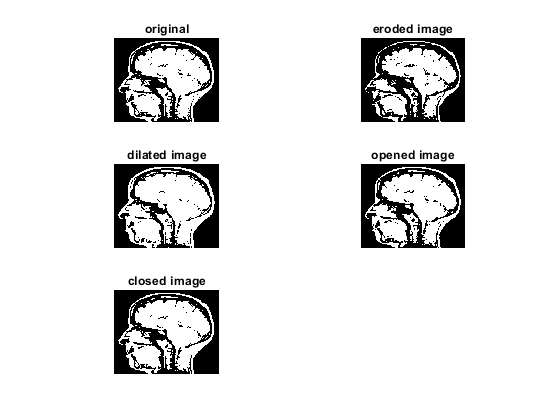

%Week4: Ali_Aleksi
%  binary morpholopy
a1 = imread('brain.jpg');
%   s
b1 = imresize(a1,[400,500]);
%  conversion of the image 
rgb1=rgb2gray(b1);
c1=imbinarize(rgb1);
%structuring element square with sides 3 using strel function 
%SE identifies the pixel in an image being processed which itself is a
%matrix
se= strel('square',3);
%eroding
erode1=imerode(c1,se);
%dilating
dilate1=imdilate(c1,se);
%Morphological opening
mopen=imopen(c1,se);
%Morphological closing
mclose=imclose(c1,se);
%subplotting original, eroded and dilated closed and opened
subplot(3,2,1);
imshow(c1),title("original");
subplot(3,2,2);
imshow(erode1),title("eroded image");
subplot(3,2,3);
imshow(dilate1),title("dilated image");
subplot(3,2,4);
imshow(mopen),title("opened image");
subplot(3,2,5);
imshow(mclose),title("closed image");

%in this brain image it can be seen that erosion has removed the pixel on
%the boundries of this object. we can see bigger black spots in eroded
%picture in comparison to the original one whereas more pixels have been
%added to the object boundary in the dilated image. We can see that black
%spots have been almost filled that is result of eroding an image. We can
%also see that the image is morphologically closed and opened. There are
%pretty little differences which can be spotted and in closed and opened image
%an opened image is eroded and then dilated while closed is an opposite of
%it

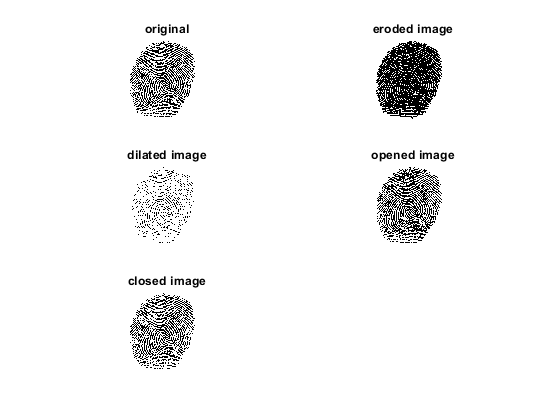

%Week4: Ali_Aleksi
%  binary morpholopy
a2 = imread('finger.jpg');
%   s
b2 = imresize(a2,[400,500]);
%  conversion of the image 
rgb2=rgb2gray(b2);
c2=imbinarize(rgb2);
%structuring element with sides 3
se2= strel('square',3);
%eroding
erode2=imerode(c2,se2);
%dilating
dilate2=imdilate(c2,se2);
%morphological opening
mopen2=imopen(c2,se2);
%Morphological closing
mclose2=imclose(c2,se2);
%subplotting
subplot(3,2,1);
imshow(c2),title("original");
subplot(3,2,2);
imshow(erode2),title("eroded image");
subplot(3,2,3);
imshow(dilate2),title("dilated image");
subplot(3,2,4);
imshow(mopen2),title("opened image");
subplot(3,2,5);
imshow(mclose2),title("closed image");

%this fig is different than other. Similarly, what was done with eroded
%function is done in this image. But this time, erosion remvoes the
%boundary pixels and dilation adds the boundary pixels to the fingerprint
%fig.


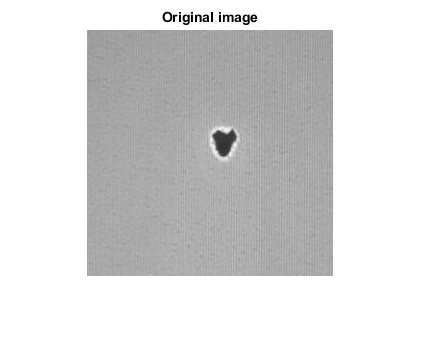

%Question 2: Semiconductor defect

fig1=imread('fig1.jpg');

imshow(fig1);

title('Original image', 'FontSize', 18);

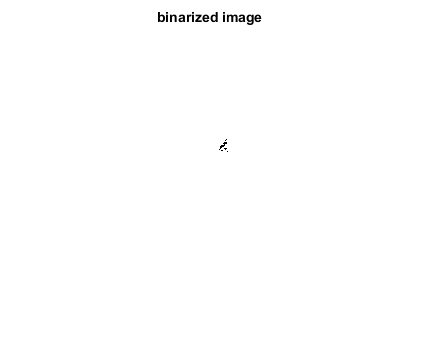

%Gray image
fig1Gray = rgb2gray(fig1);
%Binarize image using imbinarize function
b = imbinarize(fig1Gray, 0.2); % lowered threshold
figure; imshow(b)
title('binarized image')

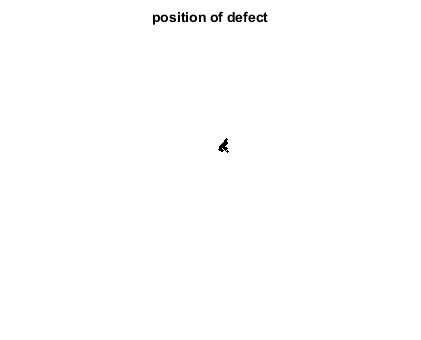

% hit-miss 
%applying hit miss operation this operation preserves pixel in an image
%whose neihbors match with SE.
%hit miss is used to find the position of the defect
position = bwhitmiss(b, SE1);
figure; imshow(position);
title('position of defect');

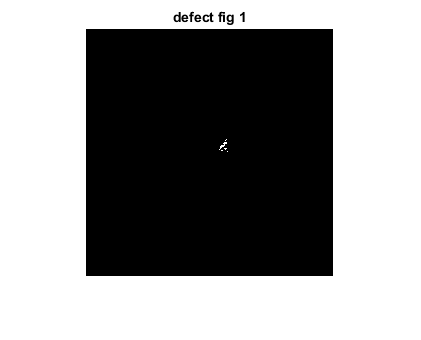

% get the defect in the image 
d = position;
%position has been found, we will use loop to grow the defect position
%once it is fully grown then loop will sstop (e.g. white area will be
%filled and the rest of the image will be turned into black)
%same goes with the other tests images below

l_d = zeros(size(d));
while ~isequal(d, l_d)
    l_d = d;
    d = ~b & imdilate(d, ones(3));
    imshow(d)
    title('defect fig 1')
 
end

%area and perimeter
a_p = regionprops(d,'Perimeter','Area');
permiter = a_p.Perimeter

permiter = 22.7680

area = a_p.Area

area = 20

%defect has been found

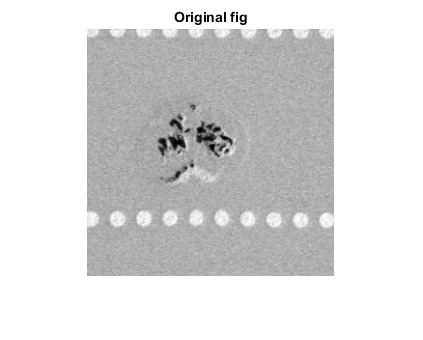


fig1=imread('fig2.jpg');

imshow(fig1);

title('Original fig', 'FontSize', 18);

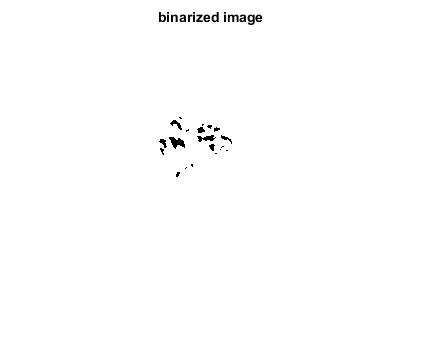

%Gray image
fig3Gray = rgb2gray(fig1);
%Binary image
b = imbinarize(fig3Gray, 0.2);
figure; imshow(b)
title('binarized image')

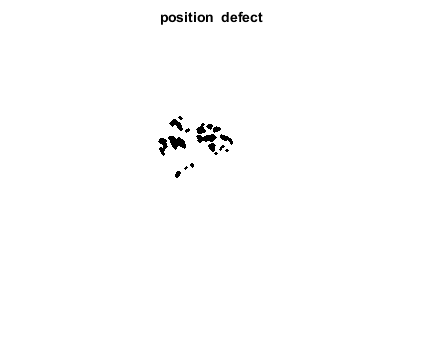

% hit-miss structuring element
position = bwhitmiss(b, SE1);
figure; imshow(position);
title('position  defect');

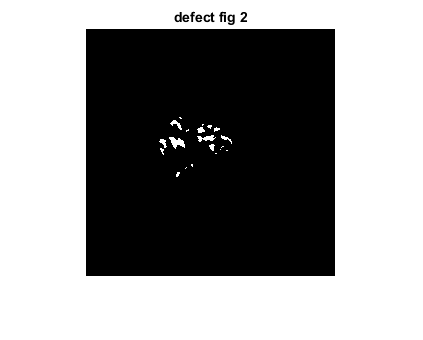

% get defect
d= position;
l_d = zeros(size(d));
while ~isequal(d, l_d)
    l_d = d;
    d = ~b & imdilate(d, ones(3));
    imshow(d)
    title('defect fig 2')
  
end

%area and perimeter 
a_p = regionprops(d,'Perimeter','Area');
permiter = a_p.Perimeter

permiter = 24.6370

area = a_p.Area

area = 36

%defect has been found

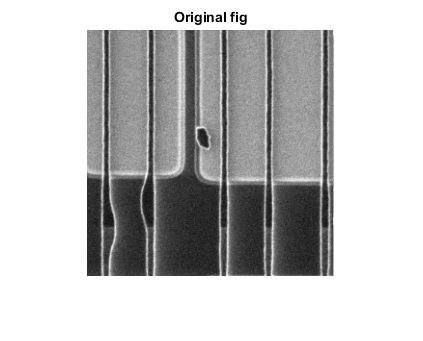

wafer3=imread('wafer1.png');
imshow(wafer3);

title('Original fig', 'FontSize', 18);

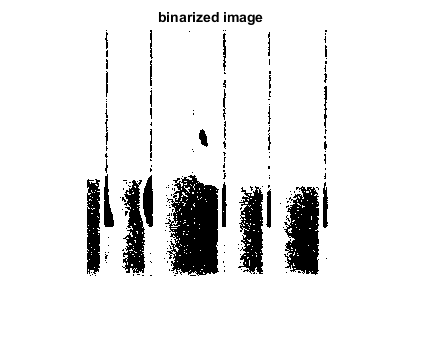

%Gray image
wafer = rgb2gray(wafer3);
%Binary image
b = imbinarize(wafer, 0.2); % 
figure; imshow(b)
title('binarized image')

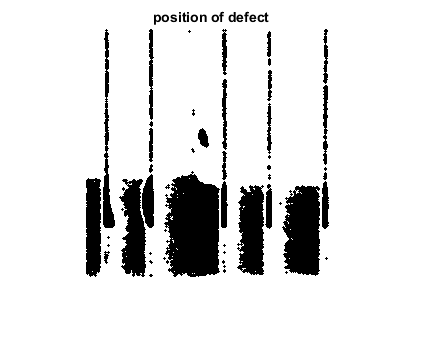

%manually defining the SE
%1 represents white, 
 
%applying hit miss operation
position = bwhitmiss(b,SE1);
figure; imshow(position);
title('position of defect');

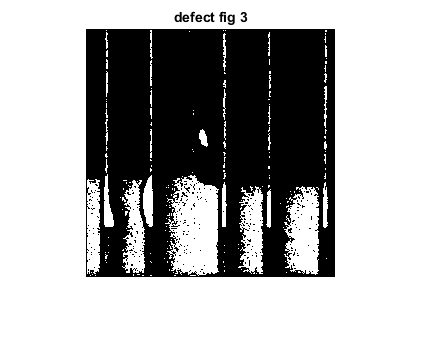

% get the defect
d = position;
l_d = zeros(size(d));
while ~isequal(d, l_d)
    l_d = d;
    d = ~b & imdilate(d, ones(3));
    imshow(d)
    title('defect fig 3')
end

a_p = regionprops(d,'Perimeter','Area');
permiter = a_p.Perimeter

permiter = 268.1930

area = a_p.Area

area = 1068

% desired result has not been found because it requires a specific SE.
%it is not possible to find the defect with the predefined SEs 

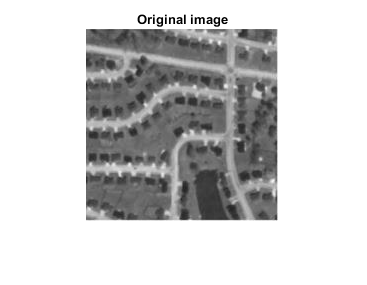

%Question 3: 
figremote=imread('remote.jpg');
imshow(figremote);
title('Original image', 'FontSize', 18);

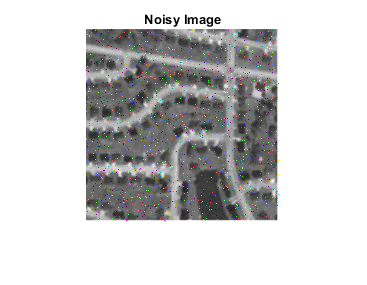

%adding salt and pepper to the original image
J = imnoise(figremote, 'salt & pepper', 0.02);
imshow(J);
title('Noisy Image', 'FontSize', 18);

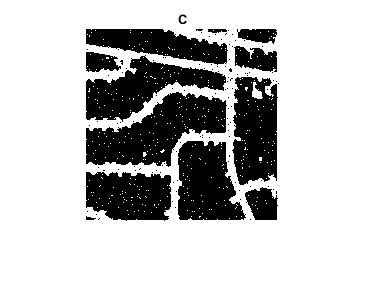

%Gray image
figGray = rgb2gray(J);
%creating binarize image using imbinarize function
BW = imbinarize(figGray); 
figure; imshow(BW)
title('C')

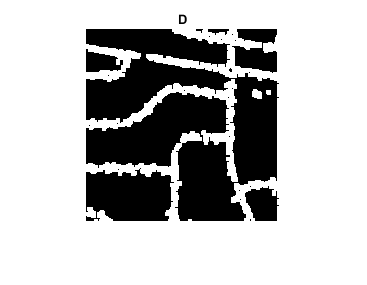

se= strel('square',4);
% initial morphological opening
opening1=imopen(BW,se);
figure; imshow(opening1)
title('D')

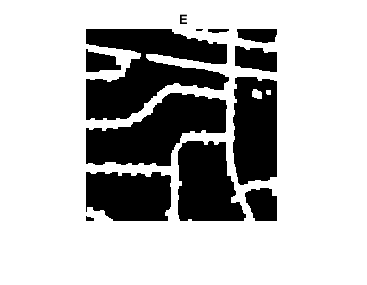

%morphological closing
closing1=imclose(opening1,se);
figure; imshow(closing1)
title('E')

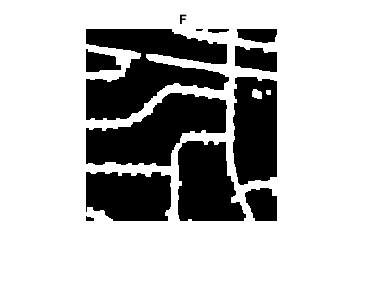

% final morphological opening
opening2=imopen(closing1,se);
figure; imshow(opening2)
title('F')

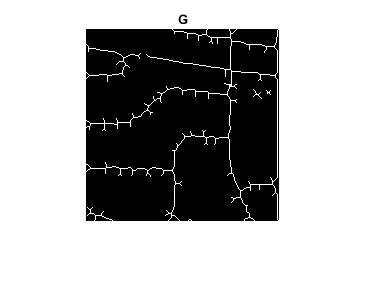

%thinning image using skel function with property skel that removes pixels
%on the boundaries of the object where inf is the number of times an
%operation is performed
skel=bwmorph(closing1,'skel',inf);
figure; imshow(skel)
title('G')

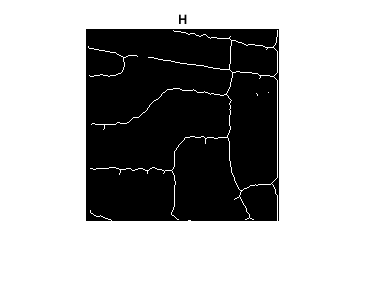

%extraxted image using bwmorp function with property thin that shrinks the
%object
extraxted = bwmorph(closing1,'thin',inf);
figure; imshow(extraxted)
title('H')

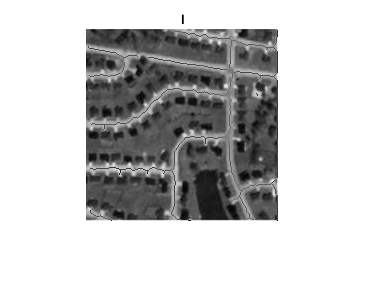

%final overlapped
C = imfuse(extraxted,figremote,'diff');
figure; imshow(C)
title('I')

%The final results have been achieved as asked in the document. There were
%minor differences in the results achieved from the images given in the
%document.Furthermore, all operations as asked in the document were
%performed to reach the final results (I).  Final image (I) resembles the
%image from the document 90%. There is still a light black line can be seen
%on the map.Therefore, results are little different than the provided final
%result image in the document.
%reference: www.stackoverflow.com
